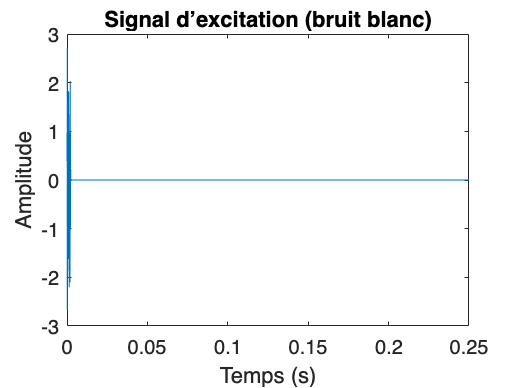


% les paramétre qu'on ajoute de base

Fe = 44100;      % fréquence d'échantillonnage (Hz)
F0 = 440;        % fréquence de la note (La)
d = 0.25;        % durée d'une note (s)

L = round(Fe/F0);   % longueur de la ligne à retard
N = round(d*Fe);    % nombre d'échantillons

% On utilise la relation T0=1/F0, donc 
%en échantillons comme : L=Fe ⋅ 












% 1.  BLANC 

e = [randn(1,L), zeros(1,N-L)];

t = (0:N-1)/Fe;

figure;
plot(t,e);
xlabel('Temps (s)');
ylabel('Amplitude');
title('Signal d’excitation (bruit blanc)');

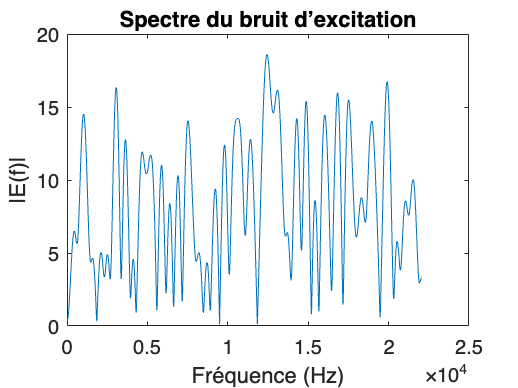














% 2. SPECTRE DU BRUIT

E = abs(fft(e, 2^nextpow2(length(e))));
E = E(1:end/2);

f = (0:length(E)-1)/length(E)*Fe/2;

figure;
plot(f,E);
xlabel('Fréquence (Hz)');
ylabel('|E(f)|');
title('Spectre du bruit d’excitation');

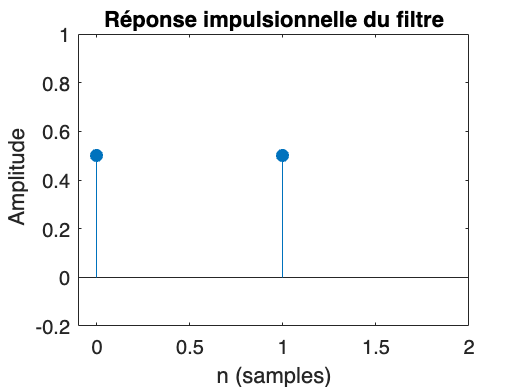











% 3.Ici on fait donc La filtre passe-bas

h = [1/2 1/2];

figure;
impz(h);
axis([-0.1 2 -0.2 1]);
title('Réponse impulsionnelle du filtre');

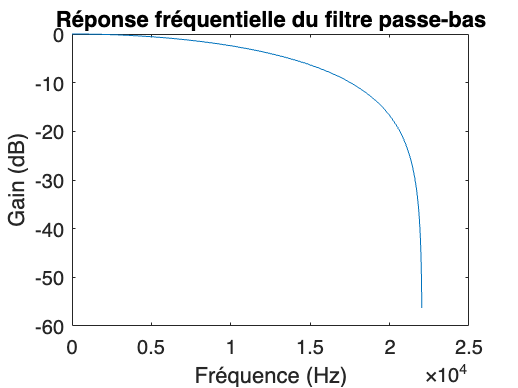


Nf = 1024;
[H,freq] = freqz(h,1,Nf,Fe);

figure;
plot(freq,20*log10(abs(H)));
xlabel('Fréquence (Hz)');
ylabel('Gain (dB)');
title('Réponse fréquentielle du filtre passe-bas');

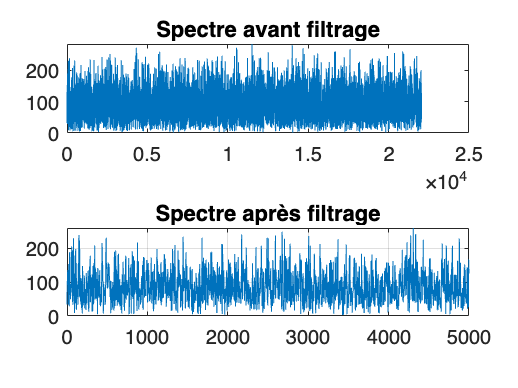












%% 4. FILTRAGE DU BRUIT (validation)

b = randn(1,N);

b_f = zeros(1,N);
b_f(1) = b(1);

for k = 2:N
    b_f(k) = 0.5*b(k) + 0.5*b(k-1);
end

B = abs(fft(b,2^nextpow2(length(b))));
B = B(1:end/2);

Bf = abs(fft(b_f,2^nextpow2(length(b_f))));
Bf = Bf(1:end/2);

f = (0:length(B)-1)/length(B)*Fe/2;

figure;
subplot(2,1,1);
plot(f,B);
title('Spectre avant filtrage');

subplot(2,1,2);
plot(f,Bf);
title('Spectre après filtrage');

xlim([0 5000]);
grid on;

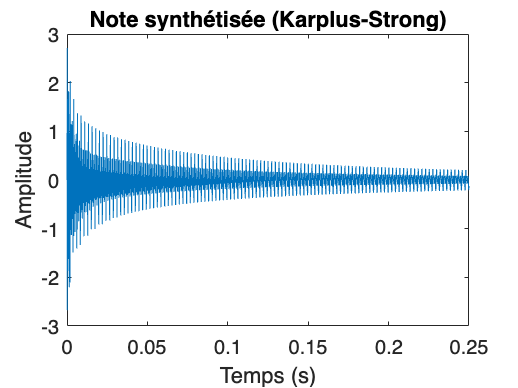


% Ici on doit verifier les harmonic
% Les pics du spectre apparaissent aux multiples de F0.
% Pour F0 = 440 Hz, on observe des pics vers :
% 440 Hz, 880 Hz, 1320 Hz, 1760 Hz, etcccc.
% Cela confirme que le signal synthétisé possède bien une structure
% harmonique donc correspondant à une corde vibrante qui marche bien.














% 5. ALGORITHME DE KARPLUS-STRONG (UNE NOTE)

a = 0.995; % cici on définie que a=0.95, car lorsque a est proche de 1, la note dure longtemps,
%et donc lorsque a diminue, l'energie decroit plus rapidement donc la note
%s'éteint plus vite, c pour ca qu'on a définie pas exact 1 mais aussi pas
%trés loin, donc à 0.995, aprés cette valeur dépend de note musicale choisi
%pour reproduire, donc on peut changer par rapport de melody qu'on veut
%crée.

s = zeros(1,N);
x = zeros(1,N);
y = zeros(1,N);
DL = zeros(1,L); % ligne à retard

for k = 2:N

    % sortie de la ligne à retard
    x(k) = DL(L);

    % filtre passe-bas (moyenne de 2 échantillons)
    y(k) = (a/2) * (x(k) + x(k-1));

    % sommation
    s(k) = e(k) + y(k);

    % décalage de la ligne à retard
    DL(2:L) = DL(1:L-1);
    DL(1) = s(k);

end


















% 6. SIGNAL TEMPOREL DE LA NOTE

t = (0:length(s)-1)/Fe;

figure;
plot(t,s);
xlabel('Temps (s)');
ylabel('Amplitude');
title('Note synthétisée (Karplus-Strong)');

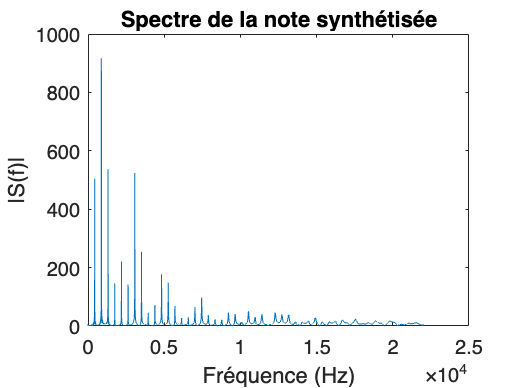


















% 7. SPECTRE DE LA NOTE

S = abs(fft(s,2^nextpow2(length(s))));
S = S(1:end/2);

f = (0:length(S)-1)/length(S)*Fe/2;

figure;
plot(f,S);
xlabel('Fréquence (Hz)');
ylabel('|S(f)|');
title('Spectre de la note synthétisée');

















% 8. MÉLODIE (NOTES SUCCESSIVES)

notes = [330 330 349 392 392 349 330 294 ... 
    262 262 294 330 330 294 294 330 ... 
    330 349 392 392 349 330 294 262 ... 
    262 294 330 294 262 262 294 262]; 

durees = [1 1 1 1 1 1 1 1 ...
    1 1 1 1 1 1 1 2 ...
    1 1 1 1 1 1 1 1 ...
    1 1 1 1 2 1 1 2];

musique = [];

for i = 1:length(notes)

    F0 = notes(i);
    d_note = d * durees(i);

    L = round(Fe/F0);
    N = round(d_note*Fe);

    e = [randn(1,L), zeros(1,N-L)];

    s = zeros(1,N);
    x = zeros(1,N);
    y = zeros(1,N);
    DL = zeros(1,L);

    for k = 2:N
        x(k) = DL(L);
        y(k) = (a/2)*(x(k) + x(k-1));
        s(k) = e(k) + y(k);

        DL(2:L) = DL(1:L-1);
        DL(1) = s(k);
    end

    musique = [musique s];

end

% normalisation pour éviter saturation numérique
musique = musique / max(abs(musique));
















% 9. EFFET GUITARE : SATURATION (DISTORSION)

musique_effet = tanh(3 * musique);
musique_effet = musique_effet / max(abs(musique_effet));














% 10. LECTURE DU SON

soundsc(musique_effet, Fe);
audiowrite('SAE_Karplus_Guitare.wav', musique_effet, Fe);













% 11. ACCORD (NOTES SIMULTANÉES)
%On veut simuler deux cordes jouées en même temp, car Ccla reproduit un accord de guitare

F1 = 330;
F2 = 392;

L1 = round(Fe/F1);
L2 = round(Fe/F2);

Nch = round(0.5*Fe);

e1 = [randn(1,L1), zeros(1,Nch-L1)];
e2 = [randn(1,L2), zeros(1,Nch-L2)];

s1 = zeros(1,Nch);
s2 = zeros(1,Nch);

DL1 = zeros(1,L1);
DL2 = zeros(1,L2);

x1_prev = 0;
x2_prev = 0;

for k = 2:Nch

    % ici on fait corde 1 
    x1 = DL1(L1);
    y1 = (a/2) * (x1 + x1_prev);
    x1_prev = x1;

    s1(k) = e1(k) + y1;

    DL1(2:L1) = DL1(1:L1-1);
    DL1(1) = s1(k);

    % et puis ici donc on fait corde 2
    x2 = DL2(L2);
    y2 = (a/2) * (x2 + x2_prev);
    x2_prev = x2;

    s2(k) = e2(k) + y2;

    DL2(2:L2) = DL2(1:L2-1);
    DL2(1) = s2(k);

end

accord = s1 + s2;% on s'additionne car principe de superposition (physique des ondes) donc signal total = signal 1 + signal 2
 
accord = accord / max(abs(accord));

% soundsc(accord, Fe);

% soundsc(accord, Fe);